# **Demo_02:    **Gyroscopic Boat stabilizer - Simulation

In this script we launch(open) a **Simulink model** that solves(or simulates) the equations of motion previously derived for the  **gyroscopic boat stabilizer**.   Specifically we're going to:

- Examine the system dynamics when the stabilization system is disabled

- Examine the system dynamics when the stabilization system is **ENABLED**

The simulations are able to reveal the significant impact that the stabilization system has on the hull "rocking" angle.

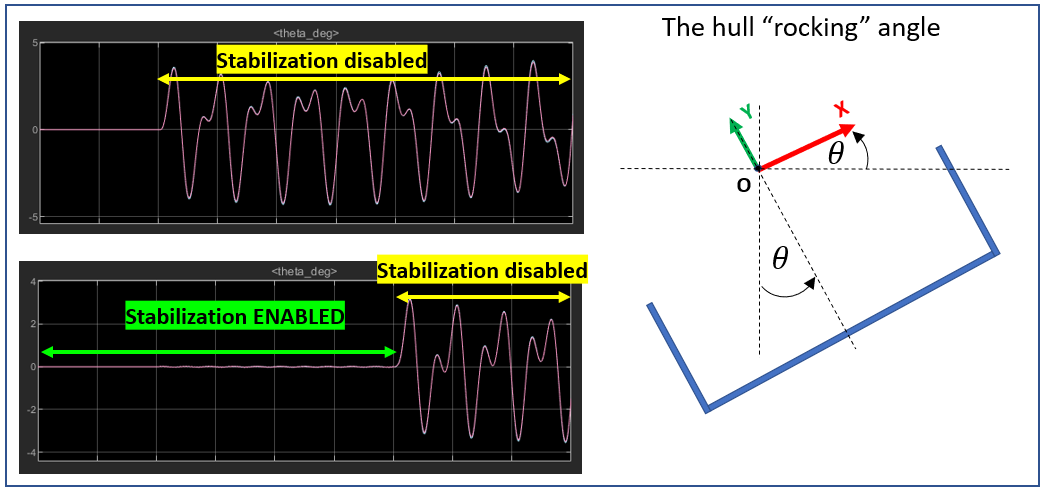  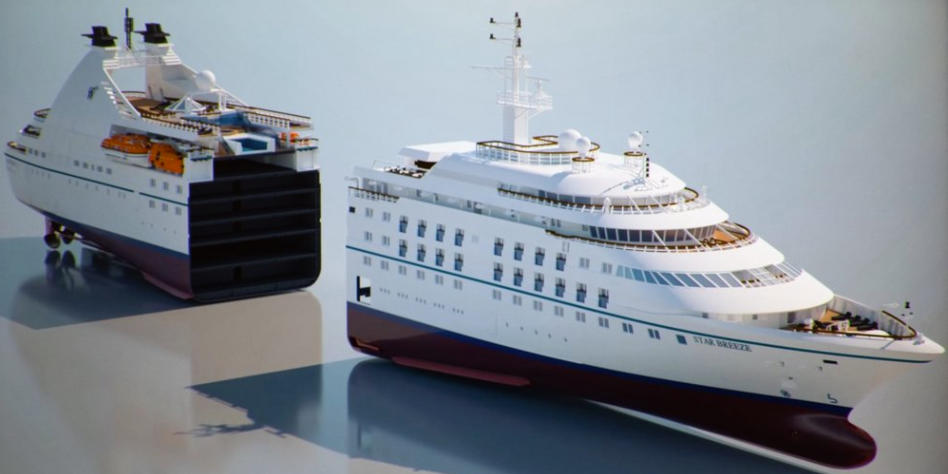

*REF:   photograph source   *[*https://www.seattletimes.com/business/stretching-a-small-cruise-ship/*](https://www.seattletimes.com/business/stretching-a-small-cruise-ship/)

`Bradley Horton : 20-Aug-2020, bhorton@mathworks.com`

## **Clear the BASE Matlab workspace**

clear ; close all; clc

## **Load parameters into the BASE Matlab workspace**

We've created a MATLAB script [`bh_boat_stabilizer_model_params.mlx`](matlab: edit bh_boat_stabilizer_model_params.mlx) that defines numerical values for the parameters needed for our model.  So let's run this script to load the parameters into the MATLAB workspace

bh_boat_stabilizer_model_params

my_res = struct with fields:
    com_sys_rel_O: [3×1 double]
               Ig: [3×3 double]
             mass: 980


my_res = struct with fields:
    com_sys_rel_O: [3×1 double]
               Ig: [3×3 double]
             mass: 753.9824


my_res = struct with fields:
    com_sys_rel_O: [3×1 double]
               Ig: [3×3 double]
             mass: 1.3427e-04


### **Open the parameter script file (just for a look):**

If you're interested in looking at the parameters used by the Simulink model, then tick the checkbox

tf_i_want_to_see_the_parameters = false;

Open the parameters file if necessary

if(true == tf_i_want_to_see_the_parameters)
   edit bh_boat_stabilizer_model_params
end

## **Open a Simulink model**

The hand derived equations of motion for the **gyroscopic boat stabilizer**  have been inserted into a Simulink file - `bh_boat_stabilizer_model.slx`.  This Simulink model also contains an alternate approach to modelling the system using Simscape Multibody.  The Simscape model also provides a nice 3-D CAD like viewer that allows us to animate the system during the simulation.  We'll also(naturally) compare the results of  our hand derived model to the corresponding results produced by Simscape.   When you open the Simulink file, note the 3 main "components" of the model:

- Some interactive widgets for configuring a specific simulation scenario

- A subsystem containing the hand derived model

- A subsystem containing the Simscape model

These 3 components are shown below:

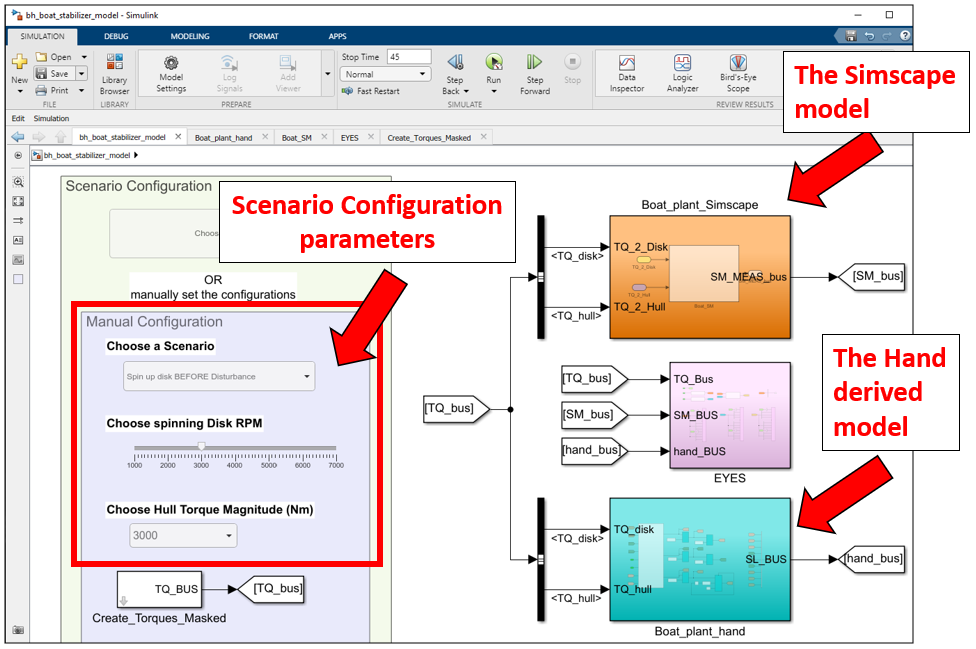

**Let's open the Simulink file:**

bh_boat_stabilizer_model

When the Simulink model opens, try the experiments summarised in the next section.

# **Experiments to try**

Try the following experiments

### **Experiment_01:   Disable the stabilization system**

- From the **Choose a Scenario** dropdown box, select "**NO Stabilization (disk is NOT spinning)**"

-     $\Longrightarrow$ this will disable the stabilization system

- From the **Choose Hull Torque Magnitude** dropdown box, select "3000"

-  $\Longrightarrow$ this specifies the magnitude of the "disturbance" torque that will be applied to the hull.  This is meant to mimic a "wave" hitting the boat.

- In this scenario, the following key events occur

- $\Longrightarrow$  the hull disturbance torque is active for the time interval:     $10\le t\le 45$

- Run the Model by clicking the Green Run button  

- Observe the Simscape animation showing the hull "rocking" side to side.  This rocking motion is represented by the $\theta$ co-ordinate.

- You can view some oscilliscope time series plots of the simulation by double clicking on the EYES subsystem and opening the scope block called "**Compare Hand vs Simscape**"  - this scope block shows the plots of the system generalised co-ordinates, ie $q_k =\left\lbrace \theta ,\;\;\phi ,\;\;\beta \right\rbrace$.  It also shows the angular velocities of these angles.

- $\Longrightarrow$NOTE: in the angular position, velocity and acceleration plots, each plot contains the hand derived result AND the Simscape result - and they are very very similar.

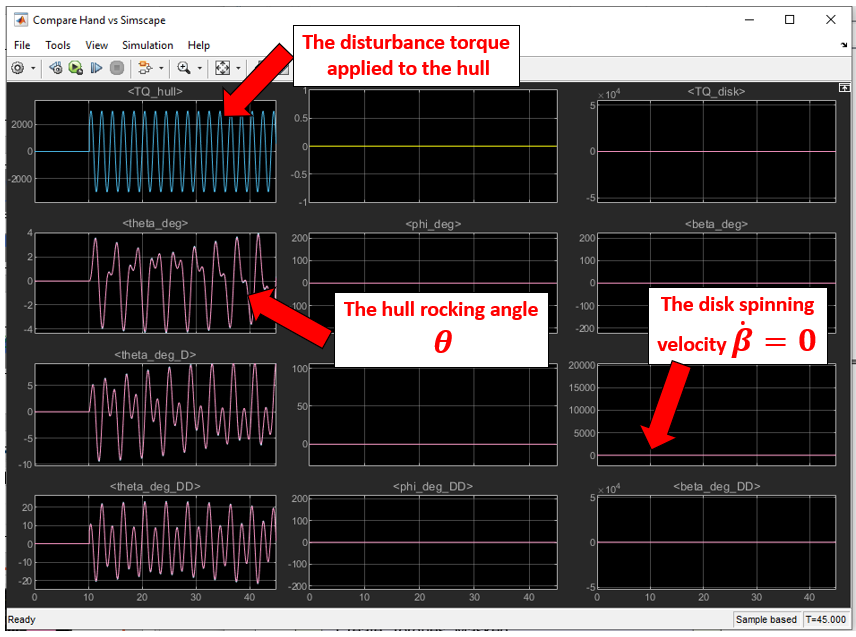

### **Experiment_02:   Enable the stabilization system**

- From the **Choose a Scenario** dropdown box, select "**Spin up disk BEFORE Disturbance**"

-     $\Longrightarrow$ this will enable the stabilization system

- From the **Choose spinning Disk RPM** dropdown box, select "3000"

- $\Longrightarrow$ this specifies the angular velocity of the spinning disk

- From the **Choose Hull Torque Magnitude** dropdown box, select "3000"

-  $\Longrightarrow$ this specifies the magnitude of the "distubance" torque that will be applied to the hull.  This is meant to mimic a "wave" hitting the boat.

- In this scenario, the following key events occur

- $\Longrightarrow$ the stabilization system is active for the time interval:            $0\le t\le 30$

- $\Longrightarrow$ the hull disturbance torque is active for the time interval:     $10\le t\le 45$

- Run the Model by clicking the Green Run button  

- Observe the Simscape animation showing the hull "rocking" side to side.  This rocking motion is represented by the $\theta$ co-ordinate.

- $\Longrightarrow$ NOTE:  while the stabilization system is active(i.e. the disk is spinning), the hull's "rocking motion" has been significantly reduced.

- $\Longrightarrow$ NOTE:  at $t=30\;\textrm{seconds}$ we then disable the stabilization system and note how the hull rocking motion resumes

- You can view some oscilliscope time series plots of the simulation by double clicking on the EYES subsystem and opening the scope block called "**Compare Hand vs Simscape**"  - this scope block shows the plots of the system generalised co-ordinates, ie $q_k =\left\lbrace \theta ,\;\;\phi ,\;\;\beta \right\rbrace$.  It also shows the angular velocities of these angles.

- $\Longrightarrow$NOTE: in the angular position, velocity and acceleration plots, each plot contains the hand derived result AND the Simscape result - and they are very very similar.

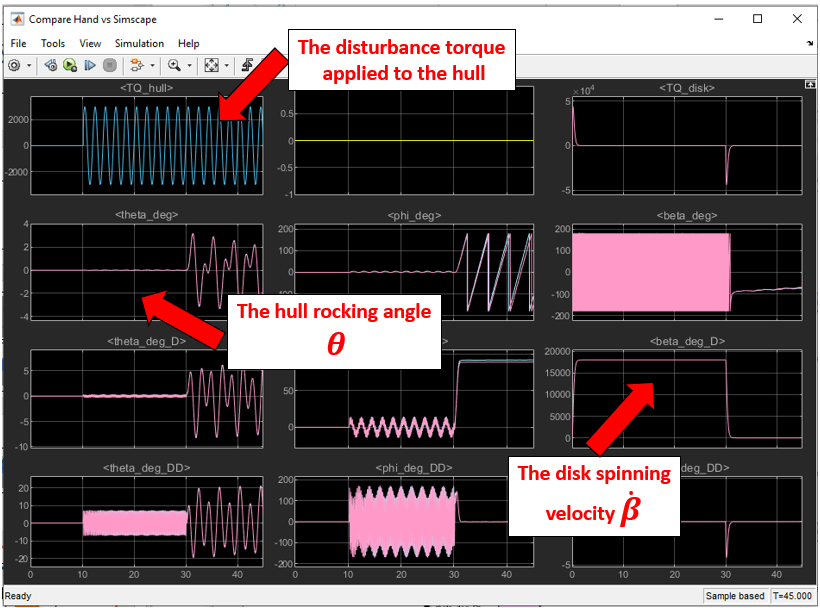

# And one more thing 

A more insightful way of seeing the effect of the gyroscopic stabilization is to "overlay" 2 Simscape models inside the Mechanics Explorer.  If you're up for it, click on the checkbox below to open a Simulink model called `bh_boat_stabilizer_model_with_double_simscape.slx` .  It might take a little longer to run .... but the "front view" in Mechanics Explorer really is worth it.

tf_open_double_trouble = true;

if(true ==tf_open_double_trouble )
    bh_boat_stabilizer_model_with_double_simscape
end